# **Discrete SEIR model for vector-borne diseases with a delay in Aquatic population with one pulse**

**Human population:**


$$H_s (t + 1) = H_s(t)\phi_m(t) (1  -  \mu_h) + N_H  \mu_h\\
H_i (t + 1) =H_s (t) (1 - \phi_m(t)) (1 - \mu_h) + H_i(t) (1 - \exp( - \gamma)) (1 - \mu_h)\\
H_r(t + 1) = H_r(t)  (1 - \mu_h)  + H_i(t)\exp(-\gamma) (1 - \mu_h) $$


**Mosquitoes population:**


$$M_s (t + 1) = M_s(t) \Psi_h(t)(1-exp(-\mu_m)) + A(t)\\
M_i (t + 1) =  M_s (1 - \Psi_h(t))  (1 - \exp( - \mu_m)) + M_i(t)(1 - \exp(- \mu_m ))$$


**With the following expressions:**

- **Mosquitoes interaction probability: **$\phi_m(t)=\left[ 1 - \frac{H_s(t) - 1}{H_s(t)} \right] ^{z_mM_i(t)\left[ \frac{H_s(t)}{N_H}\right] }$, with $N_H(t) = H_s(t) + H_i(t) + H_r(t) $

- **Human interaction probability: **$\Psi_h(t) = \left[ \frac{N_H + H_i(t)}{N_H(t)} \right]^{z_h}$, with $N_M(t) = M_s(t) + M_i(t)$

- **Recruitment expressions: ** 

- **Discrete Ricker:** $A(t) =   rN_M(t-2) \exp\left[ 1 -\frac{ N_M(t)}{C}\right]

$

**Parameters (unit time **$week^{-1}$** ):**

- $z$: number of interactions

- $\gamma$: recovery rate

- $\mu$: mortality rate

- $\alpha$: increase in mortality rate because of infection

- $r$: mosquitoes reproduction rate 

- $C$: Carrying capacity  

**Extra expressions**

- Muerte instantanea de mosquitos: $M_D(t) = (M_i(t) + M_e(t))\exp(-\alpha\mu) + M_s(t)\exp(-\mu)$ 

- Muerte instantanea de mosquitos: $H_{i_{ins}}(t) = H_e(t) \exp( - \delta_h)$

VarNames = {'H_S', 'H_I', 'H_R', 'M_S', 'M_I', 'M_D'};
OutNames = {'H_S', 'H_I', 'H_R', 'M_S', 'M_I', 'M_D', 'H_{I_ins}', 'N_H'};
ParNames = {'\gamma', '\mu_m', '\mu_h', 'z_m', 'z_h', 'r', 'C'};
FullNames = [VarNames, ParNames];
ModelName = 'CHIMERA_Vector';

Range1 = [150000 450000;    %Hs
          0 20;       %Hi
          0 0;         %Hr
          10000 500000;    %Ms
          0 100;       %Mi
          0 0          %Md                     
    ];

Range2=[
       0 1;  % gamma 
       0 1;  % mu_m
       0 1e-3;% mu_h
       0 10; % z_m
       0 10; % z_h
       0 100;% r 
       1000 150000; %C

Setting environment to work with user-defined function


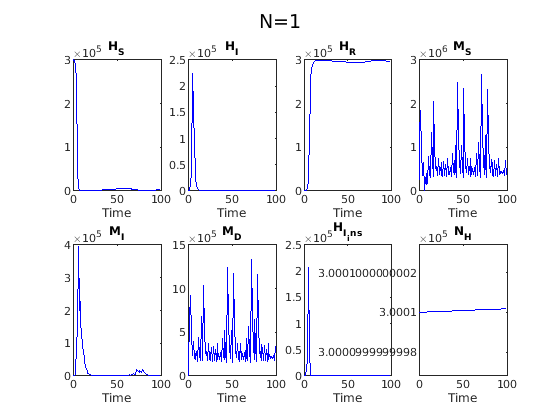

    ];


RangeT = [Range1; Range2];

D = 100;
Domain = [0 D-1];

[T,~] = gsua_dataprep(ModelName, RangeT, 'domain', Domain, 'names', FullNames, 'out_names', OutNames);
gsua_eval(T.Nominal, T);

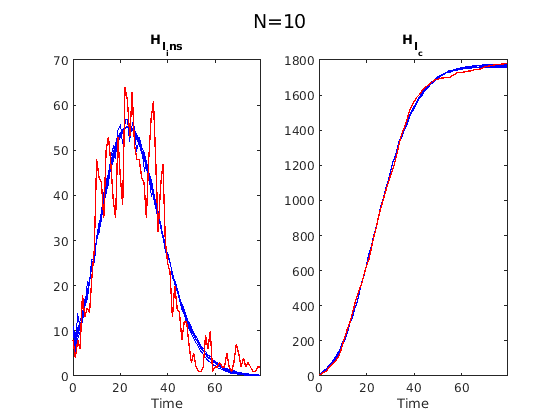

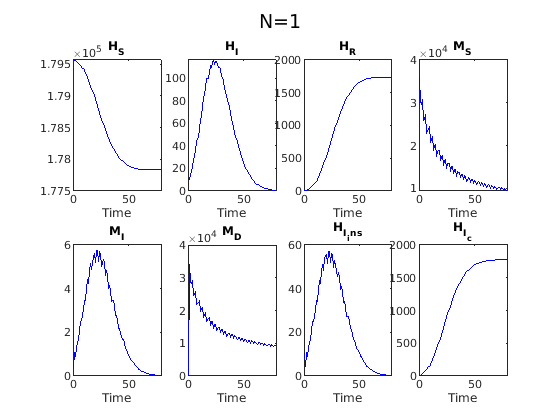

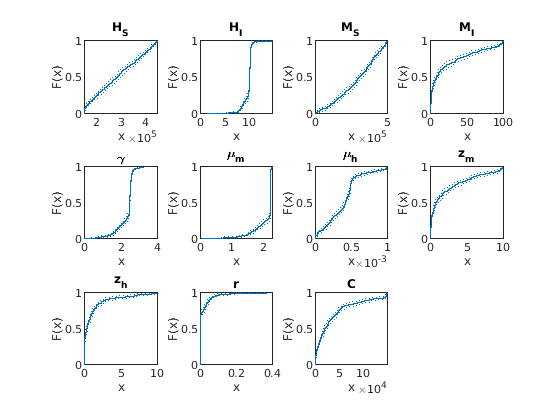

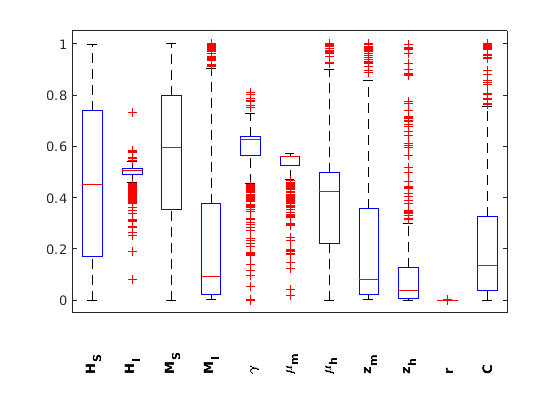

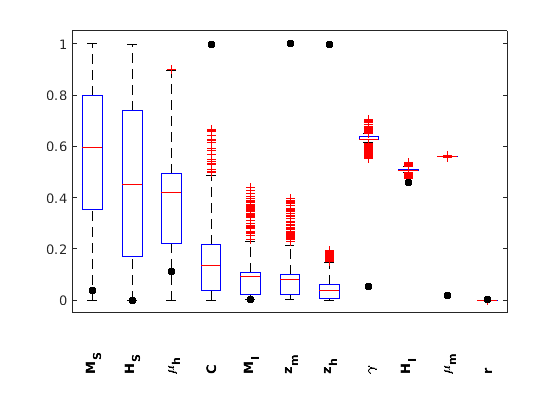

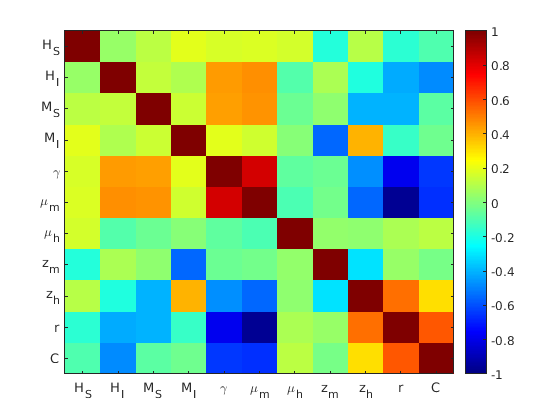

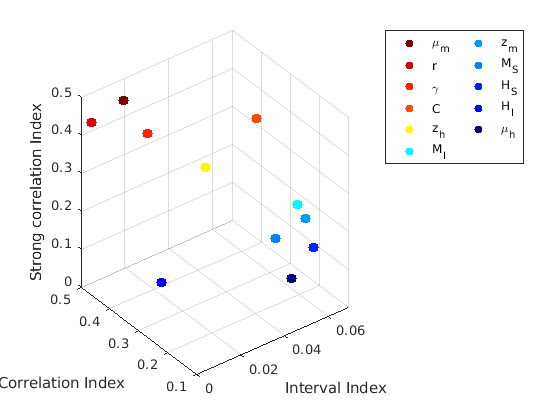

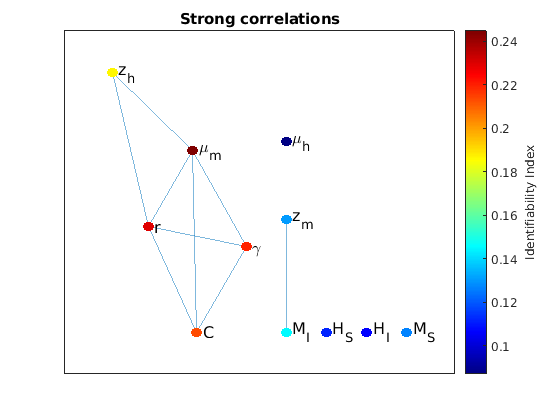

T = 11×4 table
                       Range               Nominal           Est           index  
              ________________________    __________    ______________    ________

    H_S       2.7492e+05    2.9565e+05    2.8529e+05    [1×500 double]      0.1118
    H_I           10.015        10.248        10.131    [1×500 double]     0.10633
    M_S       2.8741e+05    3.1763e+05    3.0252e+05    [1×500 double]     0.12698
    M_I           5.6885        12.445        9.0667    [1×500 double]     0.14526
    \gamma        2.4605        2.5622        2.5114    [1×500 double]      0.2188
    \mu_m         2.2053        2.2766         2.241    [1×500 double]     0.24463
    \mu_h     0.00039678    0.00044734    0.00042206    [1×500 do

load('../Data/Data_Bello_2010_2014.mat')
m = 60;
ydata = yBello(1 : m)';
ydataCum = cumsum(yBello(1 : m))';

D = length(ydata);
Domain = [0 D-1];
xdata = 0:D-1;
T.Properties.CustomProperties.Domain = Domain; 
T.Properties.CustomProperties.output = 7;

Solver = 'fmincon';

N = 100;
    
Opt = optimoptions('fmincon','UseParallel', true, 'MaxFunctionEvaluations', 30000, ...
    'MaxIterations', 3000, 'Display','off');

parfor i = 1:N
    [T_est, ResTemp] = gsua_pe(T,xdata, ydata,'solver',Solver,'N',1,'opt',Opt,'save',false);
    Residual(i) = ResTemp;
    Params(i,:) = T_est.Estfmincon;
end

[ResidualSorted, idx] = sort(Residual);
EstimatedParams = Params(idx, :);

save("ResultsDengue/Estimations_Vector.mat", "EstimatedParams", "ResidualSorted")

# Load and sort the 1000 estiamtions

T.Properties.CustomProperties.output = [7 8];
gsua_eval(EstimatedParams(1:10,:)', T, xdata, [ydata; ydataCum]);
T.Properties.CustomProperties.output = 1:8;
gsua_eval(EstimatedParams(1,:)',T, xdata);

T_ia = gsua_ia(T, EstimatedParams(1:500, :)', false, true);